clear;
clc;
addpath("../interpolation/")

% m1 = 2.0;  % (kg) Cart mass
% m2 = 0.5;  % (kg) pole mass
% l = 0.5;   % (m) pendulum (pole) length
% 
% dist = 0.8;  %How far must the cart translate during its swing-up
% maxForce = 100;  %Maximum actuator forces
% duration = 2;

m1 = 5;  % (kg) Cart mass
m2 = 1;  % (kg) pole mass
l = 2;   % (m) pendulum (pole) length

dist = 0.8;  %How far must the cart translate during its swing-up
maxForce = 200;  %Maximum actuator forces
duration = 2;
dt = 0.1;
times = 0:dt:duration;
len = size(times, 2);

## Problem Setup (Run this section after getting values from C++)

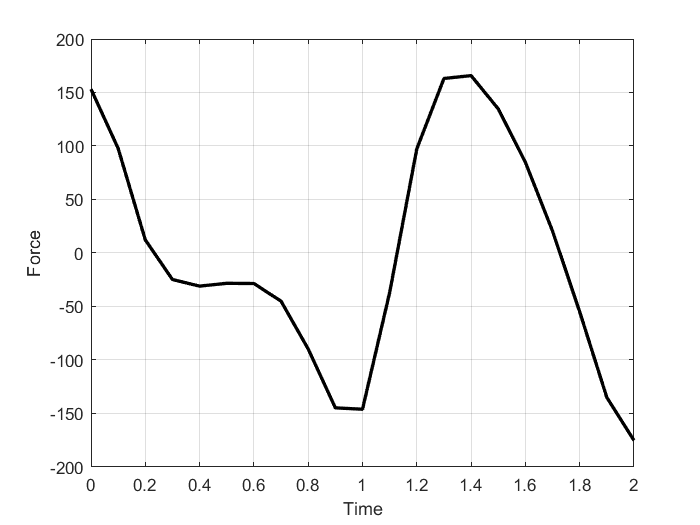

q1 = X(:,1);
q2 = X(:,2);
q1_d = X(:,3);
q2_d = X(:,4);
u = U';

figure(1);
plot(times, u,'k', 'LineWidth', 2);
axis auto;
grid on;
xlabel('Time');
ylabel('Force');

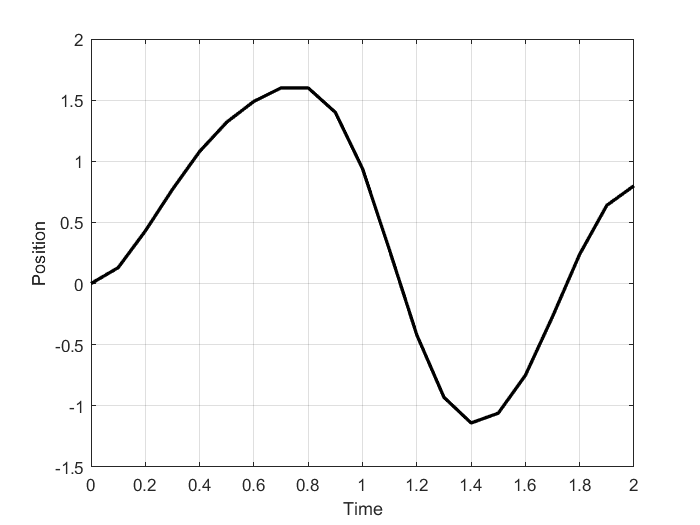


figure(2);
plot(times, q1,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Position');

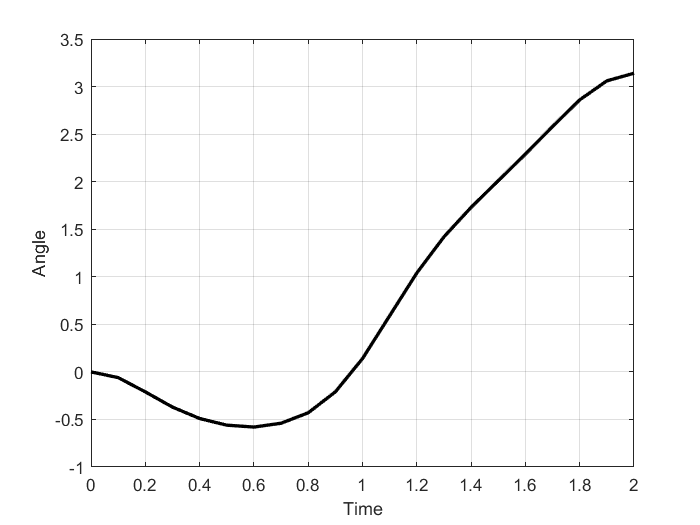


figure(3);
plot(times, q2,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Angle');

## Interpolation

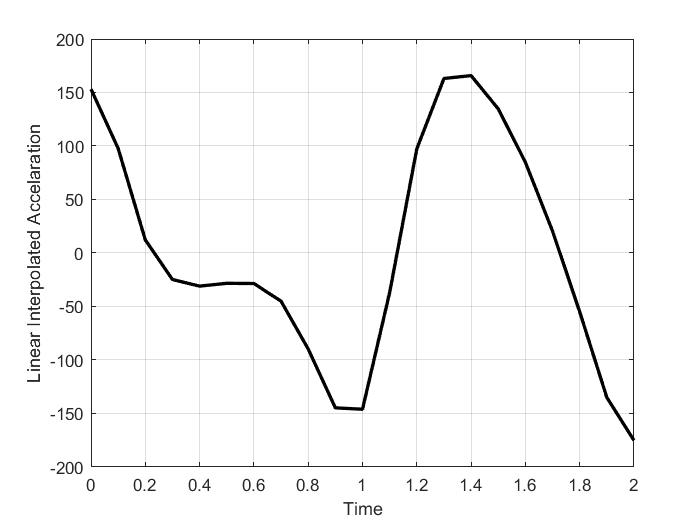

tm = 0:0.02:duration;

u_i = [];
for i = 1:size(tm, 2)
    u_i = [u_i, linear_interpolate(times, u, tm(i))];
end
figure(4);
plot(tm, u_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Linear Interpolated Accelaration');

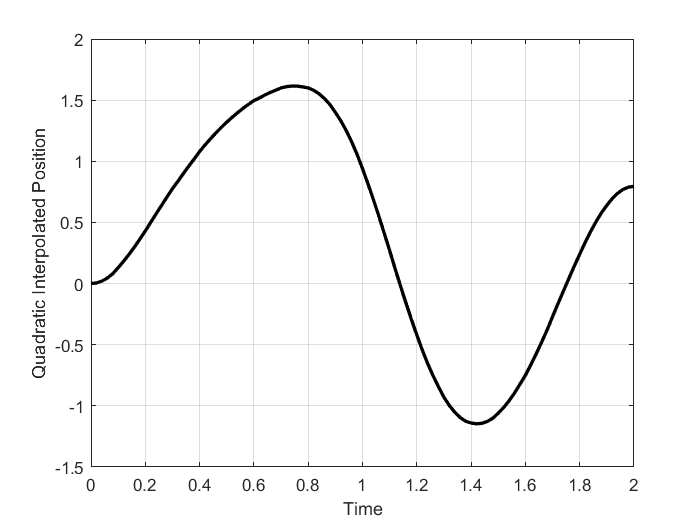


q1_i = [];
for i = 1:size(tm, 2)
    q1_i = [q1_i, quadratic_interpolate(times, q1, q1_d, tm(i))];
end
figure(5);
plot(tm, q1_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Quadratic Interpolated Position');

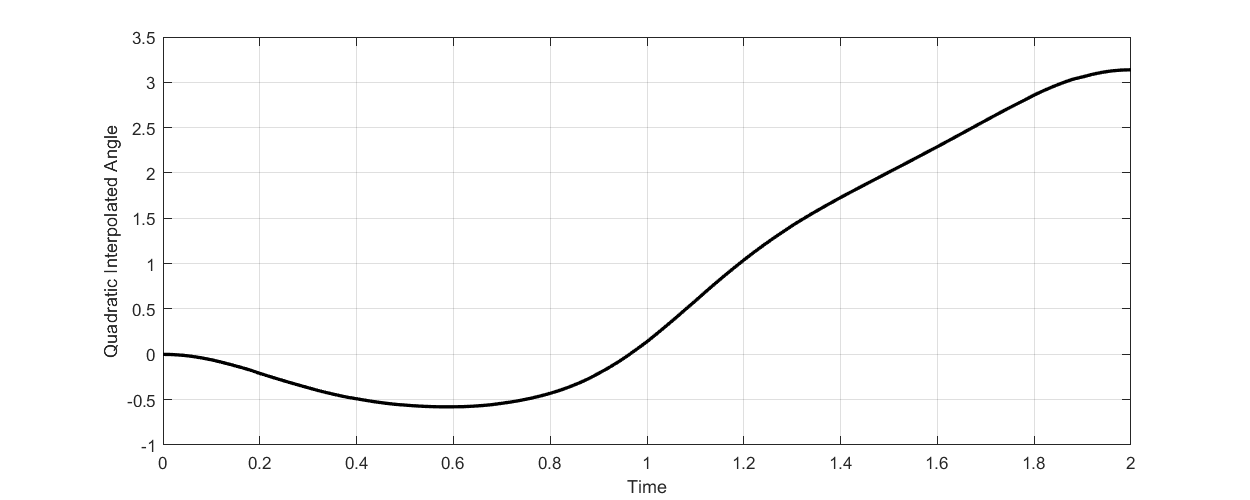


q2_i = [];
for i = 1:size(tm, 2)
    q2_i = [q2_i, quadratic_interpolate(times, q2, q2_d, tm(i))];
end
figure(6);
plot(tm, q2_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Quadratic Interpolated Angle');

## Simulation

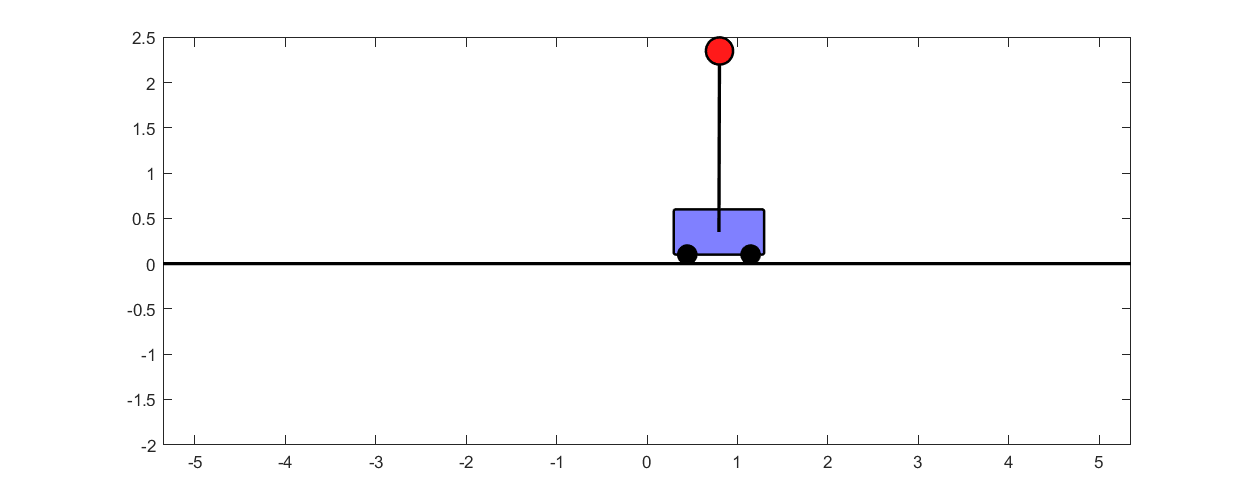

sim_data = [transpose(q1_i), transpose(q2_i)];
for k=1:1:size(tm, 2)
    drawpend(sim_data(k,:),m2,m1,l);
end